## Parameter init

clear all
clc
u_ana1 = @(x) -0.5*(x-0.5).^2 +1/8;
u_ana2 = @(x) (1 - 2*x) *heaviside(x-0.5) + x;

f1 = @(x) 1;
f2 = @(x) 2*dirac(x-0.5);

x1 =0;
xn =1;
dx = 0.1;

## Solution f =1

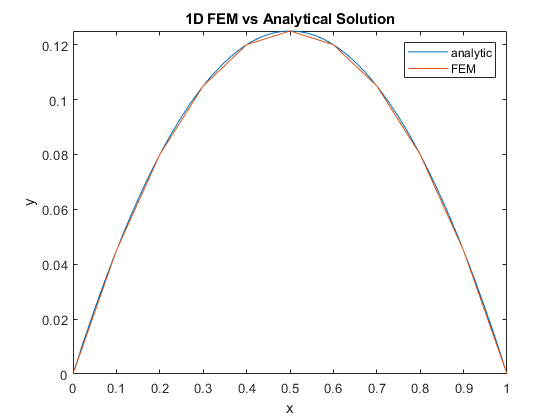

x = grid(x1,xn,dx);


fplot(u_ana1,[0 1]);
hold on

[D,b] = assmbleMatrix(x,f1);
u1 = linEqsSolver(D,b);

plot(x,u1);
hold off

xlabel('x')
ylabel('y')
title('1D FEM vs Analytical Solution')
legend('analytic','FEM')

## Solution f = 2*dirac(x-0.5)


fplot(u_ana2,[0 1]);

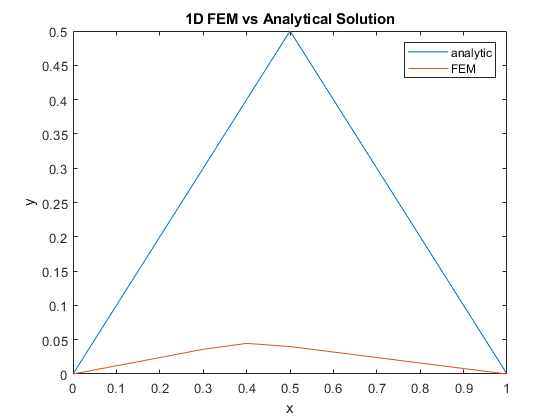

hold on

[D,b] = assmbleMatrix(x,f2);
u2 = linEqsSolver(D,b);

plot(x,u2);
hold off

xlabel('x')
ylabel('y')
title('1D FEM vs Analytical Solution')
legend('analytic','FEM')

## convergence behavior

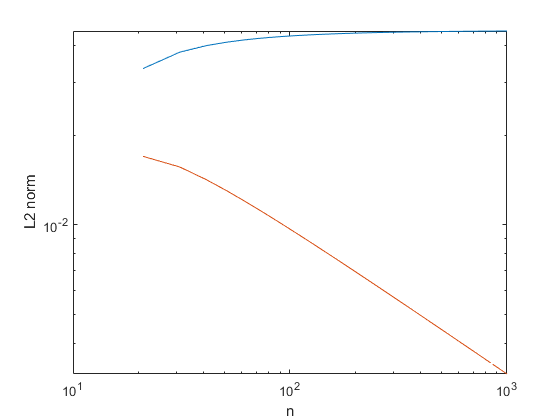

val1 = l2Error(f1,u_ana1,x1,xn);
loglog(val1(:,2),val1(:,1));

hold on
val2 = l2Error(f2,u_ana2,x1,xn);
loglog(val2(:,2),val2(:,1));

xlabel('n')
ylabel('L2 norm')